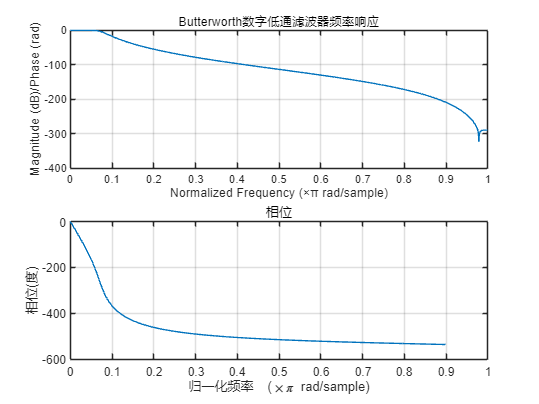

% 设计参数
wp = 0.2;       % 数字通带截止频率(rad)
ws = 0.3;       % 数字阻带截止频率(rad)
Rp = 1;         % 通带最大衰减(dB)
As = 15;        % 阻带最小衰减(dB)
T = 1;          % 采样间隔(s)

% 1. 双线性变换预畸变：将数字频率转换为模拟频率
Omegap = 2*tan(wp/2);   % 模拟通带截止频率(rad/s)
Omegas = 2*tan(ws/2);   % 模拟阻带截止频率(rad/s)

% 2. 计算Butterworth滤波器阶数
lambda = Omegas/Omegap;             % 频率比
kw = sqrt((10^(As/10)-1)/(10^(Rp/10)-1)); % 过渡带参数
N = ceil(log10(kw)/log10(lambda));  % 计算最小阶数(向上取整)

% 3. 计算3dB截止频率(使用阻带指标)
Omegac = Omegas/(10^(As/10)-1)^(1/(2*N)); % 保证阻带指标满足

% 4. 计算Butterworth极点位置
k = 1:N;    % 极点索引
theta = (pi/2) + (pi*(2*k-1))/(2*N); % 极点角度(均匀分布在左半圆)
pk = Omegac*exp(1i*theta);           % 极点坐标

% 5. 由极点构造模拟滤波器系统函数
[Bap, Aap] = zp2tf([], pk, Omegac^N); % 零极点转传递函数形式

% 6. 双线性变换为数字滤波器
[Bz, Az] = bilinear(Bap, Aap, 1/T);   % 执行双线性变换

% 7. 绘制频率响应曲线
figure;
freqz(Bz, Az, 1024);                 % 绘制幅频和相频响应
title('Butterworth数字低通滤波器频率响应');
xlabel('Normalized Frequency (×π rad/sample)');
ylabel('Magnitude (dB)/Phase (rad)');

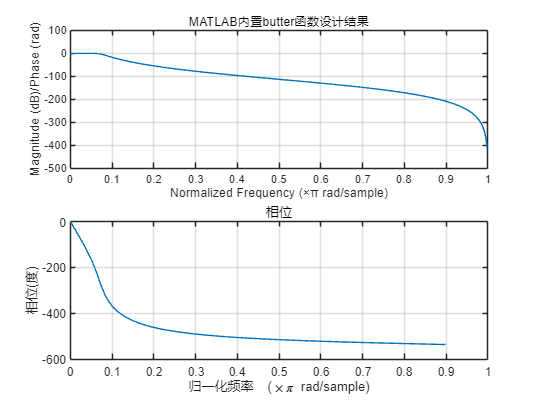


% 8. 与MATLAB内置函数比较验证
[Wn] = 2*atan(Omegac*T/2)/pi;        % 转换为MATLAB归一化频率
[Bz2, Az2] = butter(N, Wn);          % 调用内置函数设计

figure;
freqz(Bz2, Az2, 1024);               % 绘制内置函数结果
title('MATLAB内置butter函数设计结果');
xlabel('Normalized Frequency (×π rad/sample)');
ylabel('Magnitude (dB)/Phase (rad)');


% 9. 比较两个设计的系数差异(验证用)
disp('手动设计分子系数:'); disp(Bz);

手动设计分子系数:
   1.0e-04 *

    0.0139    0.0834    0.2084    0.2779    0.2084    0.0834    0.0139



disp('内置函数分子系数:'); disp(Bz2);

内置函数分子系数:
   1.0e-04 *

    0.0139    0.0834    0.2084    0.2779    0.2084    0.0834    0.0139



disp('手动设计分母系数:'); disp(Az);

手动设计分母系数:
    1.0000   -5.1260   11.0037  -12.6561    8.2228   -2.8605    0.4161



disp('内置函数分母系数:'); disp(Az2);

内置函数分母系数:
    1.0000   -5.1260   11.0037  -12.6561    8.2228   -2.8605    0.4161

